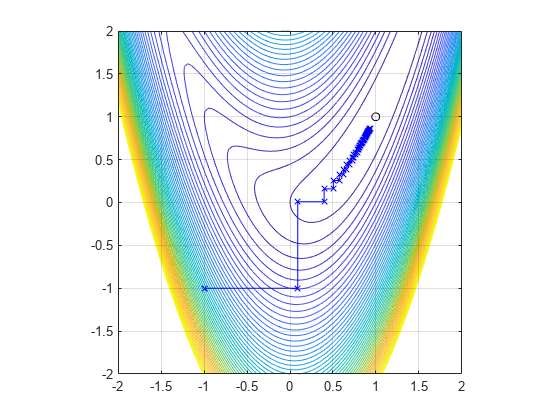

clear;clc;clf;

f = @(x) rosenbrock(x); grad = @(x) rosenbrock_grad(x);
xs = linspace(-2,2); ys = linspace(-2,2);
[Xs,Ys] = meshgrid(xs,ys);
S = [[-1;-1], [-0.8;-0.8],[-0.5;-1]];

for i=1:100
    for j=1:100
        Zs(i,j) = f([Xs(i,j),Ys(i,j)]);
    end
end

contour(Xs,Ys,Zs,0:50); hold on; grid on; axis equal; plot3(1,1,0,'ko'); 
x0 = [-1;-1];  plot(x0(1),x0(2),'rx');

cyclic_search(f,x0)

% hooke_jeeves(f,x0)
% nelder_mead(f,x0, S)
% quasi_newton(f,grad,x0)


function [val] = rosenbrock(x)
a = 1; b = 5;
val = (a-x(1))^2 + b*(x(2)-x(1)^2)^2;
end

function [val] = rosenbrock_grad(x)
a = 1; b = 5;
val = [-2*(a-x(1))+2*b*(x(2)-x(1)^2)*(-2*x(1)); 2*b*(x(2)-x(1)^2)];
end

function [a,c] = bracket_minimum(f,varargin)

switch length(varargin)
    case 0 
        x = 0; s = 1e-2; k = 2;
    case 1
        x = varargin{1}; s = 1e-2; k = 2;
    case 2
        x = varargin{1}; s = varargin{2}; k = 2;
    case 3
        x = varargin{1}; s = varargin{2}; k = varargin{3};
    otherwise
        disp("TOO MANY INPUTS")
        a = 0; c = 0; return;
end

a = x; ya = f(x); 
b = a+s; yb = f(a+s);

if yb>ya
    temp = a; a = b; b = temp;
    temp = ya; ya = yb; yb = temp;
    s = -s;
end

while true
    c = b+ s; yc = f(b+s);
    if yc > yb
        if a < c
            return
        else
            temp = a; a = c; c = temp; 
            return
        end
    end
    a = b; ya = yb; b = c; yb = yc;
    s = k*s;
end

end 

function [a,b] = golden_section_search(f,a,b,n)
fi = (1+sqrt(5))/2;
rho = fi - 1;
d = rho*b + (1-rho)*a;
yd = f(d);
for i=1:n-1
   c = rho*a+(1-rho) *b;
   yc = f(c);
   if yc < yd 
      b = d; d = c; yd = yc;
   else
       a = b; b = c;
   end   
end

if a < b
   return
else
    temp = a; a = b; b = temp; 
end

end

function [val]=cyclic_search(f,x0)
% cyclic search
xs = [x0]; plot3(xs(1,end), xs(2,end), f(xs(:,end)),'rx')
delta = inf; n = 2; iter = 1;
while abs(delta) > 1e-4
    x_1 = xs(:, iter); x = x_1;
    for i = 1:n
        d = zeros(n,1); d(i)=1;
        f_red = @(alpha) f(x+d*alpha);
        [a,c] = bracket_minimum(f_red, 0);
        [a,b] = golden_section_search(f_red,a,c,50);
        alpha = (a+b)/2;
        x = x + alpha*d;
        xs(:, end+1) = x;
        iter = iter+1;
        plot3([xs(1,end-1),xs(1,end)],[xs(2,end-1),xs(2,end)],[f(xs(:,end-1)), f(xs(:,end))],'b-x'); pause(0.1)
    end
    delta = norm(x-x_1);
    if iter > 100
        break;
    end
end
end

function [val]=hooke_jeeves(f,x0)
% hooke-jeeves
xs = [x0]; plot3(xs(1,end), xs(2,end), f(xs(:,end)),'rx');
y = f(xs(:,end));
n = length(xs);
alpha = 1; par_eps = 1e-6; gamma = 0.5; iter = 1;
while alpha > par_eps
    improved = false;
    x_best= xs(:,end); y_best = y;
    for i = 1:2
        for sgn = [-1,1]
            d = zeros(n,1); d(i)=1;
            x_n = xs(:, end)+sgn*alpha*d; 
            y_n = f(x_n);
            plot3(x_n(1,end),x_n(2,end),y_n,'rx')
            if y_n < y_best
                x_best = x_n; y_best = y_n; improved = true;
            end
        end
    end
    x = x_best; y=y_best;
    if improved == false
        alpha = alpha * gamma;
    end
    xs(:, end+1) = x;
    iter = iter+1;
    plot3([xs(1,end-1),xs(1,end)],[xs(2,end-1),xs(2,end)],[f(xs(:,end-1)), f(xs(:,end))],'b-x'); pause(0.1)
    
    if iter > 100
        break;
    end
end
end

function [val]=nelder_mead(f,x0, S)
% Nelder mead
xs = [x0]; plot3(xs(1,end), xs(2,end), f(xs(:,end)),'rx');
par_eps = 1e-6; 
plot(S(1,[1:3,1]),S(2,[1:3,1]))
delta= inf; 
alpha = 1; 
beta = 2; 
gamma = 0.5; 
iter = 1;
y = zeros(1,3);

for i = 1:3
    y(1,i) = f(S(:,i));
end

while delta > par_eps
    [y,p] = sort(y); 
    S = S(:,p);

    x_l = S(:,1); 
    x_h = S(:,end);
    x_s = S(:,end-1);

    y_l = y(1);  
    y_h = y(end); 
    y_s = y(end-1); 

    plot([x_s(1), x_h(1), x_l(1),xs(1)],[x_s(2), x_h(2), x_l(2),xs(2)], '-ko')

    x_m = mean(S(:,1:end-1),2); 
    x_r = x_m + alpha*(x_m - x_h);
    y_r = f(x_r);

    if y_r < y_l
        x_e = x_m + beta*(x_r-x_m); y_e = f(x_e);
        if y_e < y_r
            S(:,end) =x_e; y(end) = y_e;
        else
            S(:,end) =x_r; y(end) = y_r;
        end
    elseif y_r > y_s
        if y_r <= y_h
            x_h = x_r; y_h = y_r; 
            S(:, end) = x_r; y(end) = y_r;
        end
        x_c = x_m + gamma*(x_h - x_m);
        y_c = f(x_c);
        if y_c > y_h
            for i = 2:length(y)
                S(:,i) = (S(:,i)+x_l)/2;
                y(i) = f(S(:,i));
            end
        else
            S(:,end) = x_c; 
            y(end) = y_c;
        end
    else
        S(:,end) = x_r; y(end) = y_r;
    end

    delta = std(y);
    xs(:,end+1)= x_l; 
    iter = iter+1;
    plot3([xs(1,end-1),xs(1,end)],[xs(2,end-1),xs(2,end)],[f(xs(:,end-1)), f(xs(:,end))],'b-x');
    plot(S(1,[1:3,1]),S(2,[1:3,1]),'k--'); pause(0.1);

    if iter > 100
        break;
    end
end
end

function [val]=quasi_newton(f,grad,x0)
%% Quasi newton DFP
xs = x0; plot3(xs(1,end), xs(2,end), f(xs(:,end)),'rx');
g = grad(xs); Q = eye(2); iter = 1;
while norm(g) > 1e-4
    d= -Q*g;
    f_red = @(alpha) f(xs(:,end) + d*alpha);
    [a,c] = bracket_minimum(f_red); 
    [a,b] = golden_section_search(f_red,a,c,50);
    alpha = (a+b)/2;

    xs(:,end+1) = xs(:,end) + alpha*d;
    plot3([xs(1,end),xs(1,end-1)],[xs(2,end),xs(2,end-1)],[0, f(xs(:,end))],'b-x');pause(0.1);
    g_old = g;
    g = grad(xs(:,end)); 
    gamma = g - g_old;
    delta = xs(:,end) - xs(:,end-1);
    Q = Q - (Q*gamma)*(gamma'*Q)/(gamma'*Q*gamma) + delta*delta'./delta'*gamma;
    
    iter = iter +1;
    
    if iter > 100
        break
    end
end
end